cd('/Users/sushant/Desktop/ITC/JIPITE')
filename = 'krishnafinal.xlsx';
data = readtable(filename, 'VariableNamingRule', 'preserve');

data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
data.DateTime = datetime(data.DateTime);

validIdx = data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0;
data = data(validIdx, :);

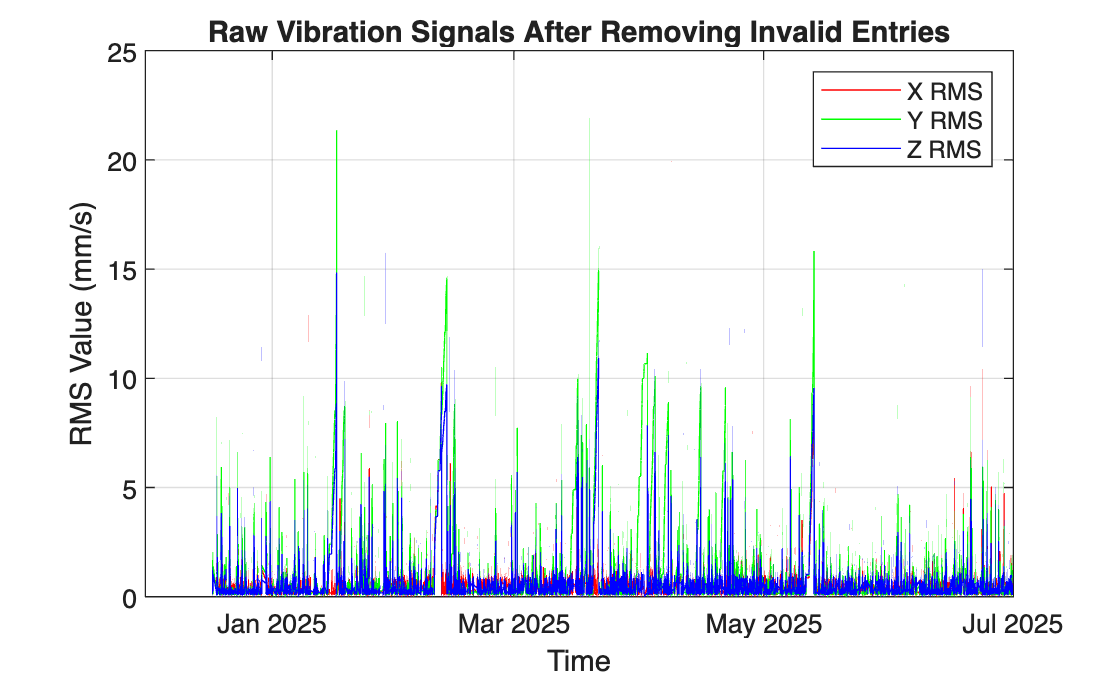

% Visualize raw vibration signals (cleaned)
figure;
plot(data.DateTime, data.X_RMS, 'r');
hold on;
plot(data.DateTime, data.Y_RMS, 'g');
plot(data.DateTime, data.Z_RMS, 'b');
xlabel('Time');
ylabel('RMS Value (mm/s)');
title('Raw Vibration Signals After Removing Invalid Entries');
legend('X RMS', 'Y RMS', 'Z RMS');
grid on;


% Step 1: Identify high-RMS indices
highRMS = data.X_RMS > 8.5 | data.Y_RMS > 8.5 | data.Z_RMS > 8.5;
highRMSIdx = find(highRMS);

fprintf("📌 High-RMS entries (X, Y, or Z > 8.5 mm/s):\n");

📌 High-RMS entries (X, Y, or Z > 8.5 mm/s):


for i = 1:length(highRMSIdx)
    idx = highRMSIdx(i);
    fprintf("Index %5d | Time: %s | X: %.2f | Y: %.2f | Z: %.2f\n", ...
        idx, string(data.DateTime(idx)), ...
        data.X_RMS(idx), data.Y_RMS(idx), data.Z_RMS(idx));
end

Index  9712 | Time: 16-Jan-2025 06:59:00 | X: 0.17 | Y: 8.51 | Z: 5.87
Index  9713 | Time: 16-Jan-2025 11:28:25 | X: 0.21 | Y: 8.53 | Z: 5.88
Index  9714 | Time: 16-Jan-2025 11:29:25 | X: 0.22 | Y: 8.55 | Z: 5.90
Index  9715 | Time: 16-Jan-2025 11:30:25 | X: 0.31 | Y: 8.57 | Z: 5.91
Index  9716 | Time: 16-Jan-2025 11:31:25 | X: 0.16 | Y: 8.59 | Z: 5.92
Index  9717 | Time: 16-Jan-2025 11:32:24 | X: 0.20 | Y: 8.61 | Z: 5.94
Index  9718 | Time: 16-Jan-2025 11:33:25 | X: 0.30 | Y: 8.64 | Z: 5.95
Index  9719 | Time: 16-Jan-2025 11:34:25 | X: 0.17 | Y: 8.66 | Z: 5.97
Index  9720 | Time: 16-Jan-2025 11:35:25 | X: 0.29 | Y: 8.68 | Z: 5.98
Index  9721 | Time: 16-Jan-2025 11:36:24 | X: 0.26 | Y: 8.70 | Z: 5.99
Index  9722 | Time: 16-Jan-2025 11:37:25 | X: 0.23 | Y: 8.72 | Z: 6.01
Index  9723 | Time: 16-Jan-2025 11:38:25 | X: 0.21 | Y: 8.74 | Z: 6.02
Index  9724 | Time: 16-Jan-2025 11:39:25 | X: 0.22 | Y: 8.77 | Z: 6.04
Index  9725 | Time: 16-Jan-2025 11:40:25 | X: 0.21 | Y: 8.79 | Z: 6.05
Index 

% Step 2: Smart ±600-sample masking only around true peaks
removeMask = false(height(data), 1);
window = 600;
lastRemovedIdx = 0;

for idx = highRMSIdx'
    % Skip if this index lies within already removed zone
    if idx - window > lastRemovedIdx
        fromIdx = max(1, idx - window);
        toIdx = min(height(data), idx + window);
        removeMask(fromIdx:toIdx) = true;
        lastRemovedIdx = toIdx;
    end
end

% Step 3: Remove those entries from data
data = data(~removeMask, :);

% Step 4: Now safely construct the features table
features = table;
features.XRMS = data.X_RMS;
features.YRMS = data.Y_RMS;
features.ZRMS = data.Z_RMS;
features.XRMS_Trend = data.XRMS_Trend;
features.YRMS_Trend = data.YRMS_Trend;
features.ZRMS_Trend = data.ZRMS_Trend;
features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
features.dXRMS = [NaN; diff(data.X_RMS)];
features.dYRMS = [NaN; diff(data.Y_RMS)];
features.dZRMS = [NaN; diff(data.Z_RMS)];

% Remove missing values from both features and data ⬅️ NEW LINE
missingMask = any(ismissing(features), 2);
features = features(~missingMask, :);
data = data(~missingMask, :);  % align data table with features

% ---- Normalize using training-only range ----
X_full = features{:,:};
numTrain = round(0.5 * size(X_full, 1));
train_min = min(X_full(1:numTrain, :));
train_max = max(X_full(1:numTrain, :));

X = (X_full - train_min) ./ (train_max - train_min);
X = max(min(X, 1), 0);  % clamp to [0,1]

% Optional detrending
% X = detrend(X);
% X = diff(X);

numTrain = round(0.5 * size(X, 1));
XTrain = {X(1:numTrain, :)'};  
Xseq   = {X'};                         

% Autoencoder
layers = [
    sequenceInputLayer(size(X, 2))
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(size(X,2))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 120, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

% Train and Predict
net = trainNetwork(XTrain, XTrain, layers, options);


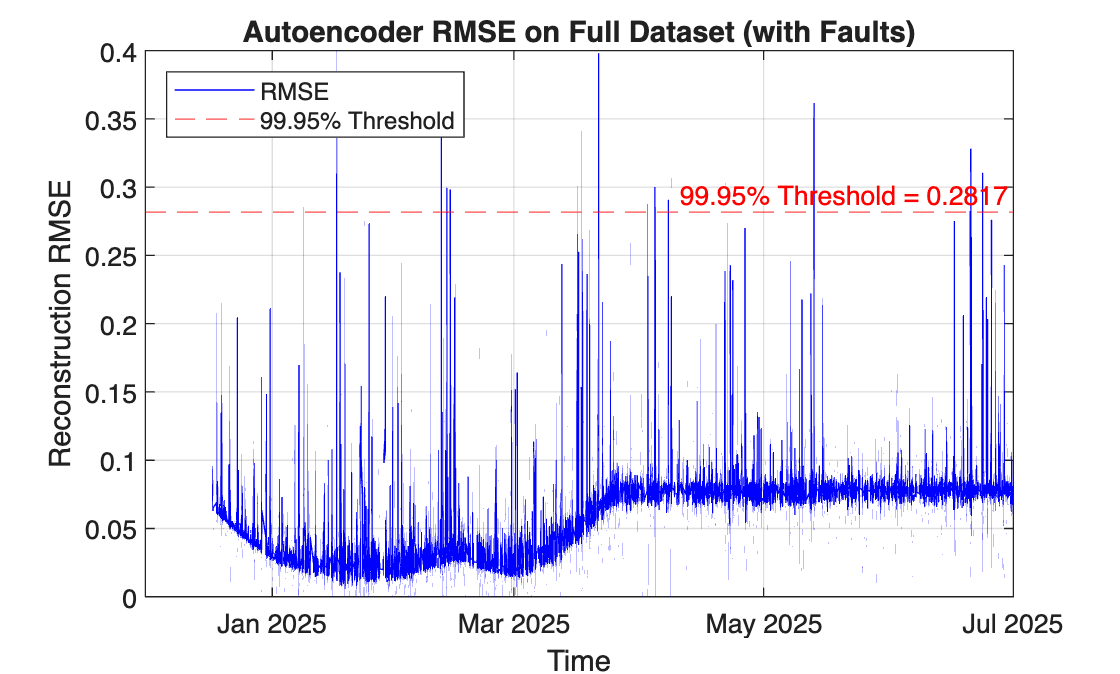

% 🧠 Assumes 'net' is your trained autoencoder from healthy data

% Reload full data (only removing zero-RMS entries)
filename = 'MX201 Vibration Data for analysis.xlsx';
dataFull = readtable(filename, 'VariableNamingRule', 'preserve');
dataFull.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
dataFull.DateTime = datetime(dataFull.DateTime);

validIdx = dataFull.X_RMS > 0 | dataFull.Y_RMS > 0 | dataFull.Z_RMS > 0;
dataFull = dataFull(validIdx, :);  % ⚠️ only remove invalid, keep faults

% Feature engineering
featuresFull = table;
featuresFull.XRMS = dataFull.X_RMS;
featuresFull.YRMS = dataFull.Y_RMS;
featuresFull.ZRMS = dataFull.Z_RMS;
featuresFull.XRMS_Trend = dataFull.XRMS_Trend;
featuresFull.YRMS_Trend = dataFull.YRMS_Trend;
featuresFull.ZRMS_Trend = dataFull.ZRMS_Trend;
featuresFull.MagRMS = sqrt(dataFull.X_RMS.^2 + dataFull.Y_RMS.^2 + dataFull.Z_RMS.^2);
featuresFull.dXRMS = [NaN; diff(dataFull.X_RMS)];
featuresFull.dYRMS = [NaN; diff(dataFull.Y_RMS)];
featuresFull.dZRMS = [NaN; diff(dataFull.Z_RMS)];
featuresFull = rmmissing(featuresFull);
dataFull = dataFull(end - height(featuresFull) + 1 : end, :);  % realign time

% Normalize using old training min-max
X_fullRaw = featuresFull{:,:};
X_fullNorm = (X_fullRaw - train_min) ./ (train_max - train_min);
X_fullNorm = max(min(X_fullNorm, 1), 0);

% Predict with autoencoder
X_testSeq = {X_fullNorm'};
Y_testPred = predict(net, X_testSeq);
reconLoss_full_full = sqrt(mean((X_testSeq{1} - Y_testPred{1}).^2, 1));
timestamps_full_full = dataFull.DateTime(end - numel(reconLoss_full_full) + 1:end);

% Plot reconstruction loss over time
figure;
plot(timestamps_full_full, reconLoss_full_full, 'b');
xlabel('Time');
ylabel('Reconstruction RMSE');
title('Autoencoder RMSE on Full Dataset (with Faults)');
grid on;

% Optional: Add threshold from clean RMSE
threshold = prctile(reconLoss_full_full(1:round(0.5*end)), 99.95);
yline(threshold, '--r', sprintf('99.95%% Threshold = %.4f', threshold));

legend('RMSE', '99.95% Threshold', 'Location', 'northwest');

% Assuming `reconLoss_full` is your RMSE vector
% and `threshold` is already defined (e.g., using prctile)

% Count how many values exceed the threshold
numAboveThreshold = sum(reconLoss_full_full > threshold);

% Print the result
fprintf('🔍 Number of RMSE values above threshold (%.4f): %d\n', threshold, numAboveThreshold);

🔍 Number of RMSE values above threshold (0.2817): 26


% Get indices where RMSE > threshold
exceedingIdx = find(reconLoss_full > threshold);

% Optionally get the corresponding timestamps_full
exceedingTimes = timestamps_full(exceedingIdx);  % assuming `timestamps_full` aligns with `reconLoss_full`

% Display sample of them
disp("Sample timestamps_full where RMSE exceeded threshold:");

Sample timestamps_full where RMSE exceeded threshold:


disp(exceedingTimes);  % print first 10 for brevity

   16-Jan-2025 15:35:33
   16-Jan-2025 17:21:35
   16-Jan-2025 17:26:36
   16-Jan-2025 17:44:39
   18-Jan-2025 16:51:11
   24-Jan-2025 16:20:01
   24-Jan-2025 16:25:01
   24-Jan-2025 16:30:01
   24-Jan-2025 16:35:01
   11-Feb-2025 07:11:05
   11-Feb-2025 07:13:05
   11-Feb-2025 07:14:05
   11-Feb-2025 07:15:05
   11-Feb-2025 07:16:05
   11-Feb-2025 07:17:05
   11-Feb-2025 07:18:05
   11-Feb-2025 07:19:05
   11-Feb-2025 07:20:05
   11-Feb-2025 07:21:05
   11-Feb-2025 07:22:05
   11-Feb-2025 07:23:05
   11-Feb-2025 07:24:05
   11-Feb-2025 07:25:05
   11-Feb-2025 07:26:05
   11-Feb-2025 07:27:05
   11-Feb-2025 07:28:05
   11-Feb-2025 07:29:05
   11-Feb-2025 07:30:05
   11-Feb-2025 07:31:05
   11-Feb-2025 07:32:05
   11-Feb-2025 07:33:05
   11-Feb-2025 07:34:05
   11-Feb-2025 07:35:05
   11-Feb-2025 07:36:05
   11-Feb-2025 07:37:05
   11-Feb-2025 07:39:05
   11-Feb-2025 07:40:05
   11-Feb-2025 07:43:05
   11-Feb-2025 07:44:05
   11-Feb-2025 07:45:05
   11-Feb-2025 07:46:05
   11-Feb-2025 0

% %% --------------------------------------------
% % 📈 Predicting RMSE 600 Steps Ahead from Sliding Windows (LSTM)
% % --------------------------------------------
% 
% % Smooth RMSE (optional)
% smoothRMSE = double(reconLoss_full);  % you can disable if needed
% 
% % Split
% rmseTrain = smoothRMSE(1:round(0.5*length(smoothRMSE)));  % train LSTM on 50%
% rmseForecastRegion = smoothRMSE(round(0.5*length(smoothRMSE))+1:end);  % forecast zone
% 
% % Define LSTM training dataset (windowed)
% windowSize = 100;
% X_lstm = {};
% Y_lstm = {};
% 
% for i = 1:(length(rmseTrain) - windowSize)
%     X_lstm{end+1} = rmseTrain(i : i + windowSize - 1);  % sequence input
%     Y_lstm{end+1} = rmseTrain(i + windowSize);          % next step target
% end
% 
% X_lstm = X_lstm';
% Y_lstm = cell2mat(Y_lstm');  % convert to numeric vector
% 
% % Define LSTM layers
% layersLSTM = [
%     sequenceInputLayer(1)
%     lstmLayer(50, 'OutputMode','last')
%     fullyConnectedLayer(1)
%     regressionLayer
% ];
% 
% optionsLSTM = trainingOptions('adam', ...
%     'MaxEpochs', 100, ...
%     'MiniBatchSize', 32, ...
%     'InitialLearnRate', 0.005, ...
%     'GradientThreshold', 1, ...
%     'Shuffle', 'every-epoch', ...
%     'Verbose', false);
% 
% fprintf("⏳ Training LSTM on RMSE (first 50%%)...\n");
% netLSTM = trainNetwork(X_lstm, Y_lstm, layersLSTM, optionsLSTM);
% fprintf("✅ LSTM training complete.\n");

% 
% %% 🔁 Rolling Window Forecasting (600 steps ahead)
% forecastHorizon = 600;
% stride = 30;
% numForecasts = floor((length(rmseForecastRegion) - windowSize - forecastHorizon) / stride) + 1;
% forecast600Results = table('Size', [numForecasts 3], ...
%     'VariableTypes', {'double','datetime','cell'}, ...
%     'VariableNames', {'WindowIndex','WindowStartTime','AllForecastedSteps'});
% 
% fprintf("📈 Starting %d rolling forecasts...\n", numForecasts);
% 
% for i = 1:numForecasts
%     idxStart = (i-1)*stride + 1;
%     idxEnd = idxStart + windowSize - 1;
%     inputSeq = rmseForecastRegion(idxStart:idxEnd);
%     inputSeq = inputSeq(:)';  % 1 × windowSize row vector
% 
%     forecastSteps = zeros(1, forecastHorizon);
%     for j = 1:forecastHorizon
%         nextVal = predict(netLSTM, {inputSeq});
%         forecastSteps(j) = double(nextVal);
%         inputSeq = [inputSeq(2:end), double(nextVal)];  % slide
%     end
% 
%     forecast600Results.WindowIndex(i) = i;
%     forecast600Results.WindowStartTime(i) = timestamps_full(round(0.5*length(smoothRMSE)) + idxStart);
%     forecast600Results.AllForecastedSteps{i} = forecastSteps;
%     fprintf("On forecast number %d\n", i);
% end
% 
% fprintf("✅ Forecasting complete. Showing sample:\n");
% disp(forecast600Results(1:10, :));
% 
% % Optional: Save results
% % writetable(forecast600Results, '600StepAheadForecasts.csv');

% 
% % Preallocate new column
% forecast600Results.NumAboveThreshold = zeros(height(forecast600Results), 1);
% 
% % Loop through the existing forecasted results
% for i = 1:height(forecast600Results)
%     forecastVec = forecast600Results.AllForecastedSteps{i};
%     forecast600Results.NumAboveThreshold(i) = sum(forecastVec > threshold/2);
% end
% 
% % Compute max forecasted value per row
% maxForecastedValue = cellfun(@max, forecast600Results.AllForecastedSteps);
% 
% % Append as new column
% forecast600Results.MaxForecastedValue = maxForecastedValue;
% 
% % Move it to 4th position
% forecast600Results = movevars(forecast600Results, 'MaxForecastedValue', 'After', 'WindowStartTime');
% 
% 
% % Rearrange columns
% forecast600Results = forecast600Results(:, [1 2 end 3:(width(forecast600Results)-1)]);
% sortedResults = sortrows(forecast600Results, 'MaxForecastedValue', 'descend');
% disp(sortedResults(1:40, :));  % Display top 10 rows
% 
% % Preallocate new column
% forecast600Results.ThresholdCrossingSteps = cell(height(forecast600Results), 1);
% 
% % Loop through each forecast and find the step indices exceeding threshold
% for i = 1:height(forecast600Results)
%     forecastVec = forecast600Results.AllForecastedSteps{i};
%     crossingSteps = find(forecastVec > threshold / 2);  % or use 'threshold' if preferred
%     forecast600Results.ThresholdCrossingSteps{i} = crossingSteps;
% end
% 
% % Move the new column to 5th position (adjust if needed)
% forecast600Results = movevars(forecast600Results, 'ThresholdCrossingSteps', 'After', 'NumAboveThreshold');

% % Find rows where the first crossing step is NOT 1
% nonFirstCrossing = cellfun(@(c) ~isempty(c) && c(1) ~= 1, forecast600Results.ThresholdCrossingSteps);
% 
% % Display them
% disp(forecast600Results(nonFirstCrossing, :));

%% --------------------------------------------
% 📈 Predicting RMSE 600 Steps Ahead from Sliding Windows (ARIMA)
% --------------------------------------------

% Use original unsmoothed RMSE if needed
smoothRMSE = double(reconLoss_full);  % or reconLoss_full directly

% Split into train and forecast regions
rmseTrain = smoothRMSE(1:round(0.5*length(smoothRMSE)));
rmseForecastRegion = smoothRMSE(round(0.5*length(smoothRMSE))+1:end);

% Parameters
windowSize = 100;
forecastHorizon = 600;
stride = 30;
numForecasts = floor((length(rmseForecastRegion) - windowSize - forecastHorizon) / stride) + 1;

% Prepare table to store results
forecast600Results_ARIMA = table('Size', [numForecasts 3], ...
    'VariableTypes', {'double','datetime','cell'}, ...
    'VariableNames', {'WindowIndex','WindowStartTime','AllForecastedSteps'});

fprintf("📈 Starting %d rolling forecasts using ARIMA...\n", numForecasts);

📈 Starting 1122 rolling forecasts using ARIMA...



% Rolling forecasting
for i = 1:numForecasts
    idxStart = (i-1)*stride + 1;
    idxEnd = idxStart + windowSize - 1;

    inputSeq = rmseForecastRegion(idxStart:idxEnd);

    % Fit ARIMA(5,1,0) model as a starting point
    model = arima(1,1,0);
    try
        estModel = estimate(model, inputSeq', 'Display', 'off');
        [forecastSteps, ~] = forecast(estModel, forecastHorizon, 'Y0', inputSeq');
    catch
        forecastSteps = nan(1, forecastHorizon);  % if model fails to converge
    end

    forecast600Results_ARIMA.WindowIndex(i) = i;
    forecast600Results_ARIMA.WindowStartTime(i) = timestamps_full(round(0.5*length(smoothRMSE)) + idxStart);
    forecast600Results_ARIMA.AllForecastedSteps{i} = forecastSteps(:)';
    fprintf("On forecast number %d\n", i);
end

On forecast number 1
On forecast number 2
On forecast number 3
On forecast number 4
On forecast number 5
On forecast number 6
On forecast number 7
On forecast number 8
On forecast number 9
On forecast number 10
On forecast number 11
On forecast number 12
On forecast number 13
On forecast number 14
On forecast number 15
On forecast number 16
On forecast number 17
On forecast number 18
On forecast number 19
On forecast number 20
On forecast number 21
On forecast number 22
On forecast number 23
On forecast number 24
On forecast number 25
On forecast number 26
On forecast number 27
On forecast number 28
On forecast number 29
On forecast number 30
On forecast number 31
On forecast number 32
On forecast number 33
On forecast number 34
On forecast number 35
On forecast number 36
On forecast number 37
On forecast number 38
On forecast number 39
On forecast number 40
On forecast number 41
On forecast number 42
On forecast number 43
On forecast number 44
On forecast number 45
On forecast number 


fprintf("✅ ARIMA forecasting complete. Sample results:\n");

✅ ARIMA forecasting complete. Sample results:


disp(forecast600Results_ARIMA(1:10, :));

    WindowIndex      WindowStartTime                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                  

% 🔢 Compute max forecasted RMSE for each row
maxForecastedValue = cellfun(@max, forecast600Results_ARIMA.AllForecastedSteps);

% ⬇️ Append the new column to the table
forecast600Results_ARIMA.MaxForecastedValue = maxForecastedValue;

% ✅ Display a few rows to confirm
disp(forecast600Results_ARIMA(1:10, :));

    WindowIndex      WindowStartTime                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                  


% 🔽 Sort the table by MaxForecastedValue in descending order
forecast600Results_ARIMA = sortrows(forecast600Results_ARIMA, 'MaxForecastedValue', 'descend');

% ✅ Display top results after sorting
disp(forecast600Results_ARIMA(1:10, :));

    WindowIndex      WindowStartTime                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                  

% 📏 Define your custom threshold
threshold = threshold/2;  % <-- replace with your desired threshold value

% 🧠 Preallocate column for indices
forecast600Results_ARIMA.ExceedIndices = cell(height(forecast600Results_ARIMA), 1);

% 🔁 Loop through each row and find exceedance indices
for i = 1:height(forecast600Results_ARIMA)
    forecastVec = forecast600Results_ARIMA.AllForecastedSteps{i};
    exceedIdx = find(forecastVec > threshold);  % get indices of exceedances

    if isempty(exceedIdx)
        forecast600Results_ARIMA.ExceedIndices{i} = NaN;  % if none, mark as NaN
    else
        forecast600Results_ARIMA.ExceedIndices{i} = exceedIdx;
    end
end

% ✅ Show sample output
disp(forecast600Results_ARIMA(1:10, {'WindowIndex','MaxForecastedValue','ExceedIndices'}));

    WindowIndex    MaxForecastedValue                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 

% %% --------------------------------------------
% % 📈 Predicting RMSE 600 Steps Ahead from Sliding Windows (GRU)
% % --------------------------------------------
% 
% % Use unsmoothed RMSE if needed
% smoothRMSE = double(reconLoss_full);  % or reconLoss_full directly
% 
% % Split RMSE signal
% rmseTrain = smoothRMSE(1:round(0.5 * length(smoothRMSE)));  % First 50% for training
% rmseForecastRegion = smoothRMSE(round(0.5 * length(smoothRMSE)) + 1:end);  % Last 50% for forecasting
% 
% % Define sliding windows for training
% windowSize = 100;
% X_gru = {};
% Y_gru = {};
% 
% for i = 1:(length(rmseTrain) - windowSize)
%     X_gru{end+1} = rmseTrain(i : i + windowSize - 1);
%     Y_gru{end+1} = rmseTrain(i + windowSize);
% end
% 
% X_gru = X_gru';
% Y_gru = cell2mat(Y_gru');  % Convert targets to vector
% 
% %% Define GRU network
% layersGRU = [
%     sequenceInputLayer(1)
%     gruLayer(50, 'OutputMode','last')  % Replace LSTM with GRU
%     fullyConnectedLayer(1)
%     regressionLayer
% ];
% 
% optionsGRU = trainingOptions('adam', ...
%     'MaxEpochs', 100, ...
%     'MiniBatchSize', 32, ...
%     'InitialLearnRate', 0.005, ...
%     'GradientThreshold', 1, ...
%     'Shuffle', 'every-epoch', ...
%     'Verbose', false);
% 
% % Train GRU
% fprintf("⏳ Training GRU on RMSE (first 50%%)...\n");
% netGRU = trainNetwork(X_gru, Y_gru, layersGRU, optionsGRU);
% fprintf("✅ GRU training complete.\n");

% 
% %% 🔁 Rolling Forecasting (600-step ahead, stride = 30)
% forecastHorizon = 600;
% stride = 30;
% numForecasts = floor((length(rmseForecastRegion) - windowSize - forecastHorizon) / stride) + 1;
% 
% forecast600Results_GRU = table('Size', [numForecasts 3], ...
%     'VariableTypes', {'double','datetime','cell'}, ...
%     'VariableNames', {'WindowIndex','WindowStartTime','AllForecastedSteps'});
% 
% fprintf("📈 Starting %d rolling forecasts with GRU...\n", numForecasts);
% 
% for i = 1:numForecasts
%     idxStart = (i-1)*stride + 1;
%     idxEnd = idxStart + windowSize - 1;
%     inputSeq = rmseForecastRegion(idxStart:idxEnd);
%     inputSeq = inputSeq(:)';  % Shape: [1 × windowSize]
% 
%     forecastSteps = zeros(1, forecastHorizon);
%     for j = 1:forecastHorizon
%         nextVal = predict(netGRU, {inputSeq});
%         forecastSteps(j) = double(nextVal);
%         inputSeq = [inputSeq(2:end), double(nextVal)];
%     end
% 
%     forecast600Results_GRU.WindowIndex(i) = i;
%     forecast600Results_GRU.WindowStartTime(i) = timestamps_full(round(0.5*length(smoothRMSE)) + idxStart);
%     forecast600Results_GRU.AllForecastedSteps{i} = forecastSteps;
% 
%     fprintf("On forecast number %d\n", i);
% end
% 
% fprintf("✅ GRU forecasting complete. Sample results:\n");
% disp(forecast600Results_GRU(1:10, :));

% % 🔢 Compute max forecasted RMSE for each row
% maxForecastedValue = cellfun(@max, forecast600Results_GRU.AllForecastedSteps);
% 
% % ⬇️ Append column
% forecast600Results_GRU.MaxForecastedValue = maxForecastedValue;
% 
% % ✅ Move it right after AllForecastedSteps (i.e., to be 3rd column)
% forecast600Results_GRU = movevars(forecast600Results_GRU, 'MaxForecastedValue', 'After', 'AllForecastedSteps');
% 
% % Set your custom threshold
% myThreshold = threshold/4;  % <-- change this value as needed
% 
% % Preallocate column for index positions
% forecast600Results_GRU.ExceedIndices = cell(height(forecast600Results_GRU), 1);
% 
% % Loop through each entry
% for i = 1:height(forecast600Results_GRU)
%     forecastVec = forecast600Results_GRU.AllForecastedSteps{i};
%     exceedIdx = find(forecastVec > myThreshold);
%     if isempty(exceedIdx)
%         forecast600Results_GRU.ExceedIndices{i} = NaN;
%     else
%         forecast600Results_GRU.ExceedIndices{i} = exceedIdx;
%     end
% end
% 
% % 🔽 Sort in descending order of max value
% sortedResults_GRU = sortrows(forecast600Results_GRU, 'MaxForecastedValue', 'descend');
% % Drop the 'AllForecastedSteps' column to hide it
% resultsForDisplay = sortedResults_GRU(:, {'WindowIndex', 'WindowStartTime', 'MaxForecastedValue','ExceedIndices'});
% % Display top entries
% disp(resultsForDisplay(1:100, :));